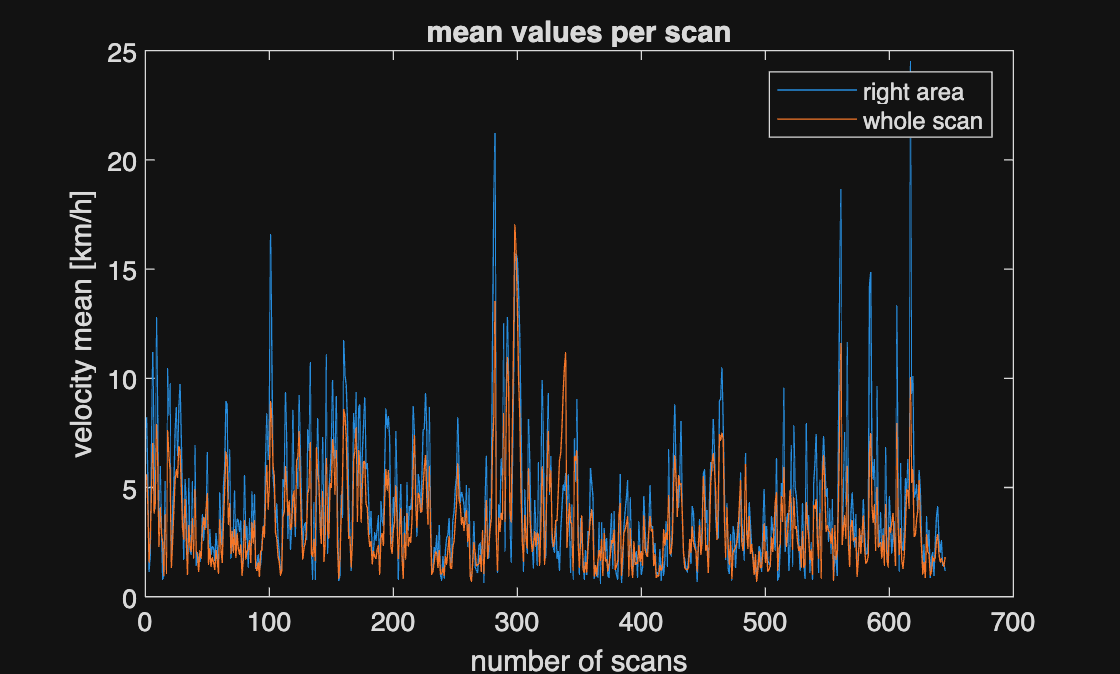

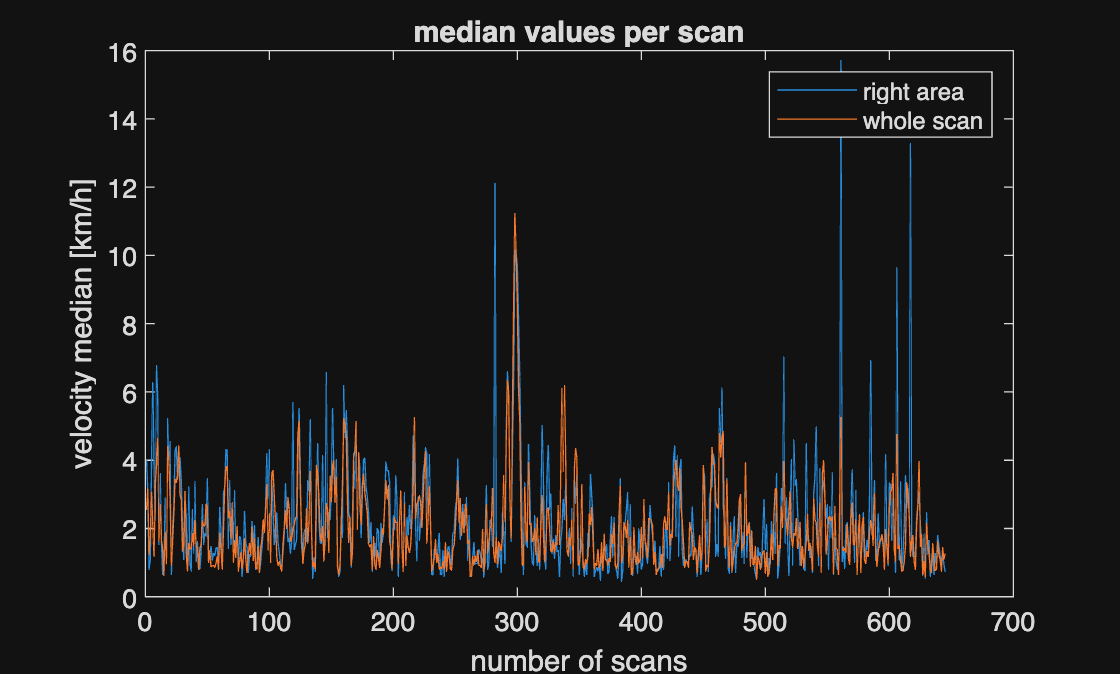

clc; clear; close all;

% change suffix from 1 to 5 to get different data files 

filepath_r_scan = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_scan_test_street_2.csv';
filepath_xy_scan = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_scan_xy_test_street_2.csv';
filepath_vx_vy = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_velocities_x_y_test_street_2.csv';
filepath_rssi = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_rssi_test_street_2.csv';

% ===== for triming long measurements uncomment the function below ===== %

% trimLidarData(filepath_xy_scan , filepath_r_scan, filepath_vx_vy, filepath_rssi, 1000, 1600)

% ===== load data ===== %

[t_r_, r_all_, t_xy_, x_all_, y_all_, t_velocity, vx_all, vy_all, v, t_rssi, rssi] = loadData(filepath_xy_scan, filepath_r_scan, filepath_vx_vy, filepath_rssi);

% ===== keep only the values with proper velocity ( vel < 20 m/s and vel > 0 m/s) ===== % 

scanPointNumbers = 421; % files come with 421 points now, earlier measurements contained the full scan (811 points per scan)
[x_filtered, y_filtered, vx_filtered, vy_filtered, v_filtered, rssi_filterd, r_filtered]= filterAllValuesWithProperVelocities(x_all_, y_all_, vx_all, vy_all, v, rssi, r_all_, scanPointNumbers);

% ===== segmentation, clustering, tracking ===== %

[x_points_in_critical_area, y_points_in_critical_area] = ExtractPointsInCriticalArea(x_filtered, y_filtered); 
segments = clusterSegments(x_points_in_critical_area, y_points_in_critical_area);
clusters = mergeSegmentsToClustersPerScan(segments);
clusters_with_id = trackClustersBetweenScans(clusters);
object_properties = classifyClusters(clusters_with_id);  % objects: id, mean of all lengths for this id, category
[v_mean, v_median, point_index_median_velocities] = computeMeanMedianVelocity(v_filtered, r_filtered, scanPointNumbers);

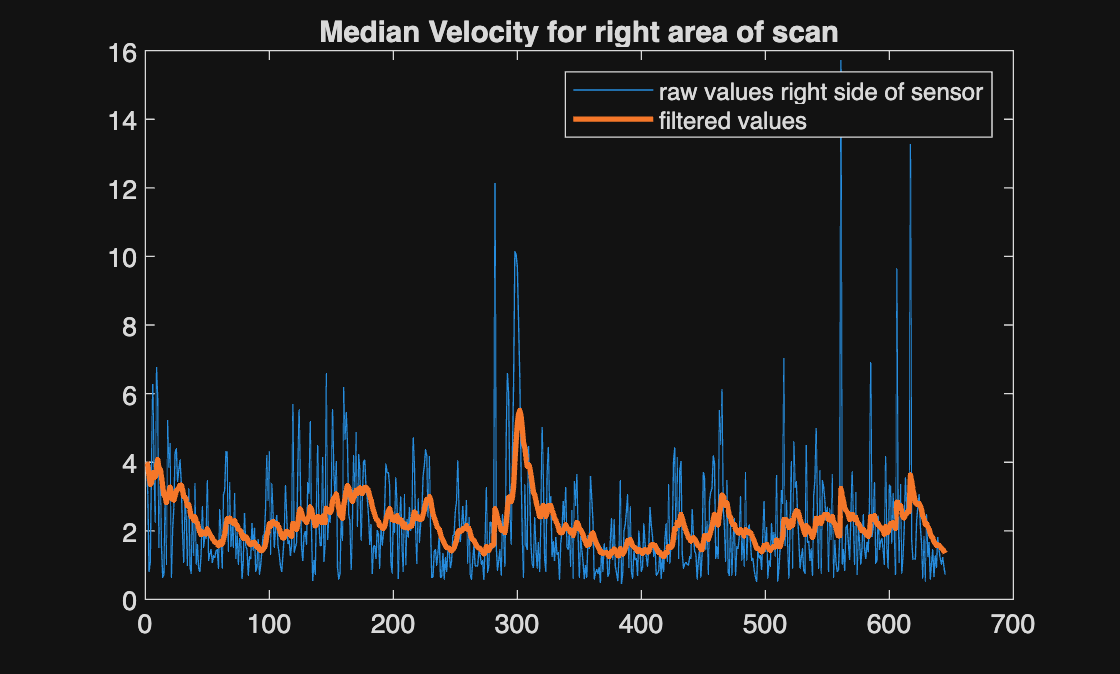

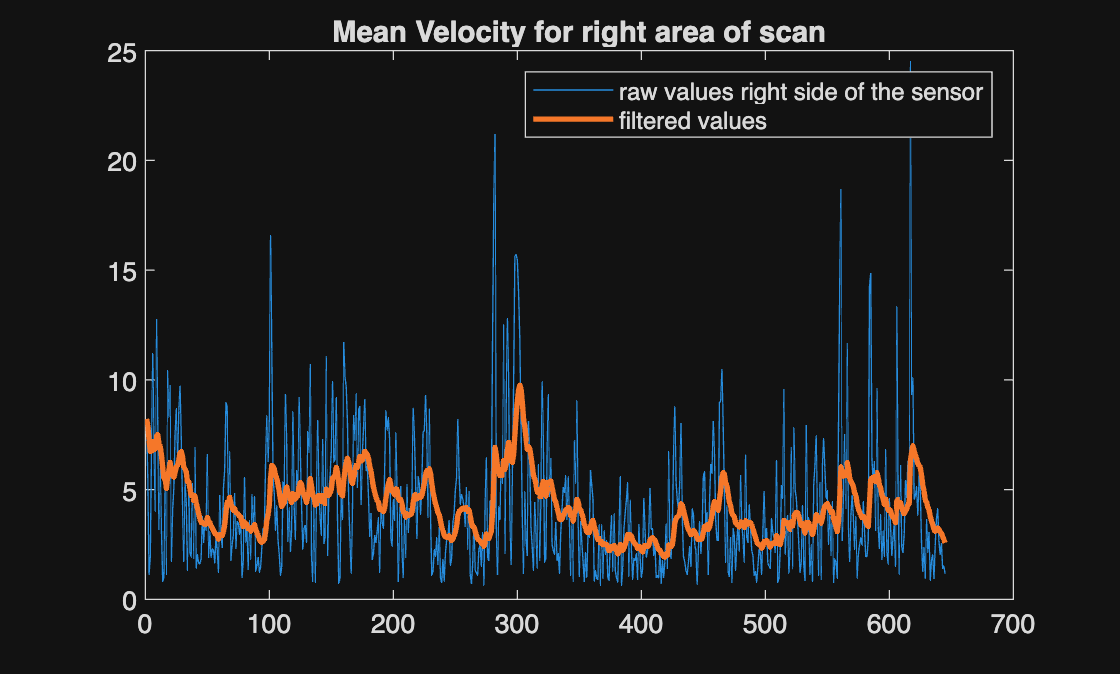

[alphafiltered_median, alphafiltered_mean] = alphaFilter(v_median(:,1), v_mean(:,1)); % alpha filter to estimate the ego velocity

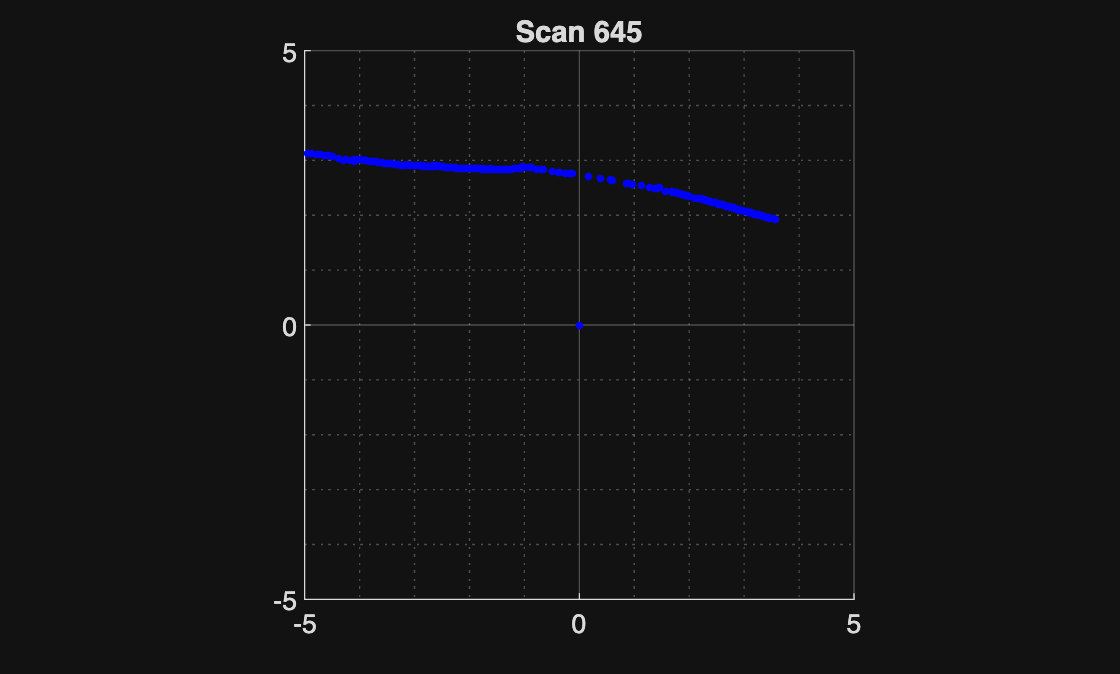

dangerousClusters = detectDangerousObject(clusters_with_id, object_properties, alphafiltered_mean); 
plotObjects(x_filtered, y_filtered, clusters_with_id, object_properties);


% ===== compute and plot peak velocities ===== %

% v_median_right_area = v_median(:,1);
% peakVelocities = detectPointWithPeakVelocity(v_median_right_area, point_index_median_velocities, rssi_filterd, r_filtered, alphafiltered_median);
% plotPointsWithDangerousVelocity(x_filtered, y_filtered, peakVelocities);

% ===== theta (the angle between the vector of velocities: (vx,vy)) ===== %

% plotTheta(x_all_, y_all_, vx_all, vy_all);
% plotTheta(x_filtered, y_filtered, vx_filtered, vy_filtered);

% ================== the end ================== %


